# Taller7 - LGR

clc, clear all, close all;

## **Funciones de transferencia**

### $G_{ol} (s)=\frac{N(s)}{D(s)}$; $\;\;\;\;\;\;\;\;\;\;\;\;\;G_{cl} (s)=\frac{G_{ol} (s)}{1+G_{ol} (s)H\left(s\right)}$

num = [1 3];
den = [1 5 20 16 0];
H = 1;
Gol = tf(num, den)

Gol =
 
             s + 3
  ---------------------------
  s^4 + 5 s^3 + 20 s^2 + 16 s
 
Continuous-time transfer function.
Model Properties


Gcl = feedback(Gol, H)

Gcl =
 
               s + 3
  -------------------------------
  s^4 + 5 s^3 + 20 s^2 + 17 s + 3
 
Continuous-time transfer function.
Model Properties


## Calcular ceros y polos

zs = roots(num)

zs = -3

ps = roots(den)

ps =    0.0000 + 0.0000i
  -2.0000 + 3.4641i
  -2.0000 - 3.4641i
  -1.0000 + 0.0000i


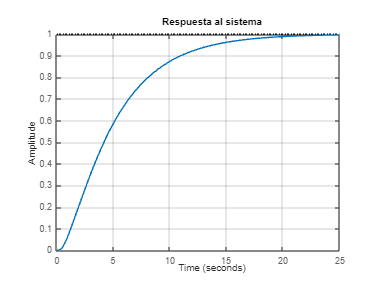

figure()
step(Gcl); grid("on");
title("Respuesta al sistema")

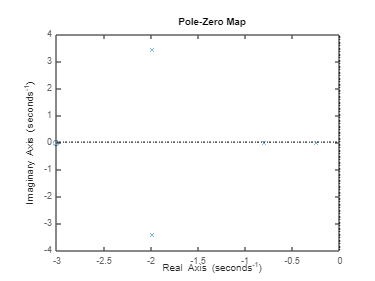

figure()
pzmap(Gcl)

## 1.3.1 Graficar de forma manual los polos y ceros

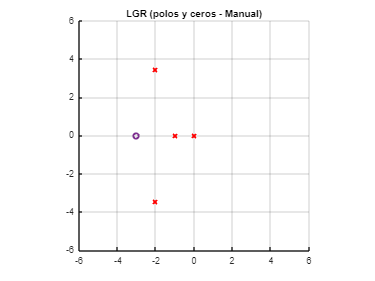

figure()
hold on; grid on; axis('square');
axis([-6 6 -6 6]);
plot(real(zs), imag(zs), 'o', 'Color', [0.49 0.18 0.56], 'LineWidth', 2); % Ceros
plot(real(ps), imag(ps), 'rx', 'LineWidth', 2); % Polos
title('LGR (polos y ceros - Manual)');

## Número de polos y ceros

np = length(ps)

np = 4

nz = length(zs)

nz = 1

n_asintotas = np - nz

n_asintotas = 3

## 1.3 Graficar Centroide

#### 
$$\theta_k =\frac{(2k+1)180^{\circ } }{n_p -n_z },~~k=0,1,\ldots,n_p -n_z -1;\;\;\;\;\;\;\;$$

$$\sigma_0 =\frac{\sum \textrm{Re}(p_i )-\sum \textrm{Re}(z_i )}{n_p -n_z }$$


asintotas_angulos = (180/pi) * ((2*(0:n_asintotas-1) + 1)*pi) / n_asintotas

asintotas_angulos =     60   180   300


sigma0 = (sum(real(ps)) - sum(real(zs))) / n_asintotas      % Centroide

sigma0 = -0.6667

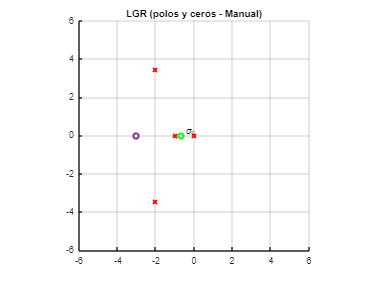

plot(sigma0, 0, 'go', 'LineWidth', 2);     % Circulo centroide
text(sigma0+0.2, 0.2, '\sigma_0');

## 1.3.4 Graficamos las líneas de las asintotas

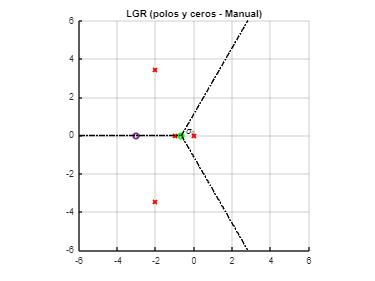

x = sigma0:0.1:6;
y1 = sqrt (3) * (x - sigma0);
y2 = -y1;
xa = -6:0.1:sigma0;
ya = zeros(1, length(xa));
plot (x, y1, 'k-.');
plot (x, y2, 'k-.');
plot (xa, ya, 'k-.');

## Cruce eje imaginario jw (x=0)

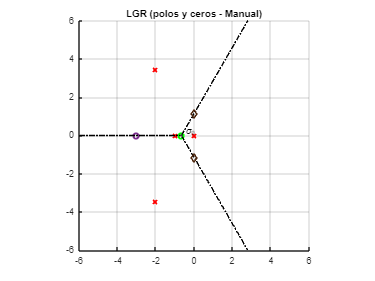

plot(0,  sqrt(3)*sigma0, 'd', 'LineWidth', 2, 'MarkerEdgeColor', [0.3 0.15 0.05]);
plot(0, -sqrt(3)*sigma0, 'd', 'LineWidth', 2, 'MarkerEdgeColor', [0.3 0.15 0.05]); 

## Condición de puntos de llegada / salida del LGR

### 
$$\begin{array}{l}
K(s)=-\frac{1}{G_{ol} (s)H(s)};\;\;\;\;\;\\
\frac{dK(s)}{ds}=0\;\;\;\;\;\;\Longrightarrow \;\;\;\;s_0 \in \textrm{LGR}~~\textrm{tal}\;\textrm{que}~~\frac{dK(s_0 )}{ds}=0
\end{array}$$


s = sym('s');
k = -1/((poly2sym(num, s)/poly2sym(den, s))*poly2sym(H, s));
dK_ds = diff(k, s);
[num_dK, ~] = numden(dK_ds);
p_llegada = double(vpa(solve(num_dK==0, s), 5));  % dK_ds = 0
for i = 1:length(p_llegada)
    s0 = p_llegada(i);
    
    % Evaluar K en el punto candidato
    K_eval = double(subs(k, s, s0));
    
    % Condición de pertenencia al LGR: K real y positivo
    if abs(imag(K_eval)) < 1e-3 && real(K_eval) > 0
        plot(real(s0), imag(s0), 'ks', 'LineWidth', 2);
    end
end

## Rango de K sea Estable

### 
$$0<K<K_{crit} ~~\Rightarrow ~~\textrm{sistema}\;\textrm{estable}$$


[GM, PM, Wcg, Wcp] = margin(Gol);
K_crit = GM

K_crit = 33.3225

den_cl = den + K_crit*[0 0 0 num];

% Raíces del sistema en Kcrit
s_all = roots(den_cl);
idx = abs(real(s_all)) < 1e-3;   % 1e-3 aprox = 0
s_crit = s_all(idx);             % polos críticos reales

plot(real(s_crit), imag(s_crit), 'dm', 'LineWidth', 4)
text(real(s_crit)+0.2, imag(s_crit)+0.2, '$k_{crit}$', 'Interpreter','latex');

### **Calcular los angulos de salida**

### 
$$\theta =180^{\circ } -\sum_{i=1}^{n_p } \angle \left(s_0 -p_i \right)+\sum_{j=1}^{n_z } \angle \left(s_0 -z_j \right)$$


polos_c = ps(imag(ps) ~= 0)   % solo polos complejos (a+jb; b!=0)

polos_c =   -2.0000 + 3.4641i
  -2.0000 - 3.4641i


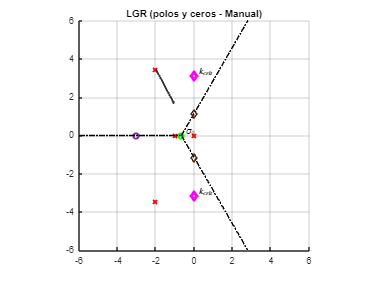

ang_p =   120.0000
   90.0000
  106.1021


ang_z = 73.8979

theta = -62.2042


for s0 = polos_c.'  % .': traspuesto columna por fila
    ang_p = angle(s0 - ps(ps ~= s0));
    ang_z = angle(s0 - zs);
    ang_p = rad2deg(ang_p)
    ang_z = rad2deg(ang_z)

    theta = 180 - sum(ang_p) + sum(ang_z);
    theta = mod(theta + 180, 360) - 180   % normalizar

    quiver(real(s0), imag(s0), ...
           cosd(theta), sind(theta), ...
           2, 'Color',[0.2 0.2 0.2], 'LineWidth',2);
    break
end

## Calcular raíces del denominador GOL

### 
$$\textrm{LGR}=\left\lbrace D(s)+KN(s)=0,\;K\ge 0\right\rbrace$$


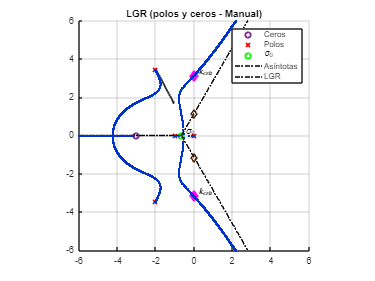

% Rango de ganancias (0, INF, paso)
K = linspace(0,500,1000);

[num_cl, den_cl] = tfdata(Gol,'v');
for i = 1:length(K)
    poli_car = den_cl + K(i)*[zeros(1,length(den_cl)-length(num_cl)), num_cl];
    lgr = roots(poli_car);     % Polos CL
    
    plot(real(lgr), imag(lgr), '.', 'Color', [0 0.2 0.8]);
end
legend('Ceros', 'Polos', '\sigma_0', 'Asíntotas', "LGR");

## Comprobacion

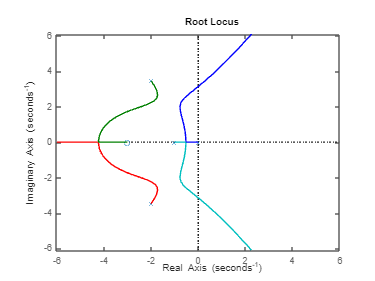

figure()
rlocus(Gol)
xlim([-6.0 6.0]); ylim([-6.1 6.1]);